% WaveFlashBarObjectLoomIndROIs
% A. Cairns
% 11.16.23

% For code with detailed notes on this process 
% look at fullBarSweep4DindROIs.m

%% Fig. 02b  Individual ROIs: delF/F(position in degrees)
% function [Fig_04b, Fig_04c] = fullBarSweep4DindROIs(exp, info, param)

% Info: There are N flies and each fly has a 4x'M' double
% (the four rows are epochs: Rbar, Lbar, Ubar, Dbar.
% 'M' is ROIs per fly which varies for each fly,
% i.e. some flies have M=21 ROIs, some have M=34, etc)

% Variables
Nflies = size(info.analysis{1,1}.indFly, 2); % # flies
t_s = info.analysis{1,1}.timeX/1000; % time in sec

% Dummy Variables
totData = [];
SqR = []; SqL = [];
SqD = []; SqU = [];
FullON = []; FullOFF = [];
BarR = []; BarL = [];
ObjR = []; ObjL = [];
LoomOFF = [];

%% I. Create Matrices: 'totData' = all the data, 'X'bar for each epoch (X=R,L,D,U)
% for loop to create a matrix, 'ROIcolEpochRow'
% totData is a cell where each col is a diff ROI, rows are epochs, and vals are delF/F
for flyfly = 1:Nflies
    ROIcolEpochRow = info.analysis{1,1}.indFly{1,flyfly}.p6_averagedTrials.snipMat;
    indflydata = reshape(ROIcolEpochRow, [], 1); % Reshape to a col vec
    % Each 'flyfly' willadd to the matrix not replace the value
    totData = [totData; indflydata]; % Concatenate: '[totData; indflydata]'
end

% EVERY: 1st element is 'Rbar', 2nd: 'Lbar', 3rd: 'Dbar', 4th: 'Ubar'
% create for loop to make a cell mats of individual epochs
numROIs = size(totData, 1);
numROIs/11

ans = 11

for ii = 1:11:numROIs
    SqR = [SqR; totData(ii)]; 
    SqL = [SqL; totData(ii+6)];
    SqD = [SqD; totData(ii+1)]; 
    SqU = [SqU; totData(ii+7)];
    FullON = [FullON; totData(ii+2)]; 
    FullOFF = [FullOFF; totData(ii+8)];
    BarR = [BarR; totData(ii+3)]; 
    BarL = [BarL; totData(ii+9)];
    ObjR = [ObjR; totData(ii+4)]; 
    ObjL = [ObjL; totData(ii+10)];
    LoomOFF = [LoomOFF; totData(ii+5)];
end

% %% II. Plots 'Fig_05b' and 'Fig_05c'
% % Convert t (sec) -> x (degrees)
% epochProbeDur = [exp.params(:).duration];
% epochDur = epochProbeDur(param.interleave_epochs+1:end);
% pos0 = [exp.params(:).relativeX];
% pos0 = pos0(param.interleave_epochs+1:end);
% delPos = [exp.params(:).dX];
% delPos = delPos(param.interleave_epochs+1:end);
% stimPos = cell(1, length(delPos)); % Create a cell array to store the positions
% stimEndPos = ones(length(delPos),1);
% for jj = 1:length(delPos)
%     stimPos{1,jj} = pos0(jj) + t_s * delPos(jj);
%     stimEndPos(jj) = pos0(jj) + (epochDur(jj)/60) .* delPos(jj);
% end

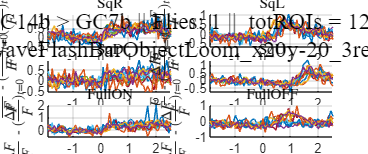

%% Plot 'Fig_05b': v = 15, 30, 60
Fig_02b = figure('Units', 'normalized', 'OuterPosition', [0, 0, 1, 1]);
for jj = 1:length(SqR) % this might be an issue if the epochs aren't the same size!!!!!!!!!!
    subplot(3,2,1); hold on; % Rbar subplot
    hold on;
    plot(t_s,SqR{jj,1})
    title('SqR', 'Interpreter', 'latex')
    % xline(-90, '-')
    % xline(90, '-')
    xlabel('$x^\circ$', 'Interpreter', 'latex');
    ylabel('$\frac{\Delta F}{F}$ - $(\frac{\Delta F}{F})_{t = 0}$', 'Interpreter', 'latex');
    grid on;
    % xlim([-95 115])
    subplot(3,2,2); hold on; % Lbar subplot
    plot(t_s,SqL{jj,1})
    title('SqL', 'Interpreter', 'latex')
    % xline(-90, '-')
    % xline(90, '-')
    xlabel('$x^\circ$', 'Interpreter', 'latex');
    ylabel('$\frac{\Delta F}{F}$ - $(\frac{\Delta F}{F})_{t = 0}$', 'Interpreter', 'latex');
    grid on;
    % xlim([-285 145])

    subplot(3,2,3); hold on; % Rbar subplot
    hold on;
    plot(t_s,SqD{jj,1})
    title('SqD', 'Interpreter', 'latex')
    % xline(-90, '-')
    % xline(90, '-')
    xlabel('$x^\circ$', 'Interpreter', 'latex');
    ylabel('$\frac{\Delta F}{F}$ - $(\frac{\Delta F}{F})_{t = 0}$', 'Interpreter', 'latex');
    grid on;
    % xlim([-95 115])
    subplot(3,2,4); hold on; % Lbar subplot
    plot(t_s,SqU{jj,1})
    title('SqU', 'Interpreter', 'latex')
    % xline(-90, '-')
    % xline(90, '-')
    xlabel('$x^\circ$', 'Interpreter', 'latex');
    ylabel('$\frac{\Delta F}{F}$ - $(\frac{\Delta F}{F})_{t = 0}$', 'Interpreter', 'latex');
    grid on;
    % xlim([-285 145])
% change titles
    subplot(3,2,5); hold on; % Rbar subplot
    hold on;
    plot(t_s,FullON{jj,1})
    title('FullON', 'Interpreter', 'latex')
    % xline(-90, '-')
    % xline(90, '-')
    xlabel('$x^\circ$', 'Interpreter', 'latex');
    ylabel('$\frac{\Delta F}{F}$ - $(\frac{\Delta F}{F})_{t = 0}$', 'Interpreter', 'latex');
    grid on;
    % xlim([-95 115])
    subplot(3,2,6); hold on; % Lbar subplot
    plot(t_s,FullOFF{jj,1})
    title('FullOFF', 'Interpreter', 'latex')
    % xline(-90, '-')
    % xline(90, '-')
    xlabel('$x^\circ$', 'Interpreter', 'latex');
    ylabel('$\frac{\Delta F}{F}$ - $(\frac{\Delta F}{F})_{t = 0}$', 'Interpreter', 'latex');
    grid on;
    % xlim([-285 145])
end
sgtitle({[num2str(param.cellType),' > ',num2str(param.sensor),' || Flies: ', num2str(info.analysis{1,1}.numFlies),' ||  totROIs = ', num2str(numROIs)], param.stim}, 'FontSize', 14, 'FontName', 'Times New Roman', 'Interpreter', 'none');

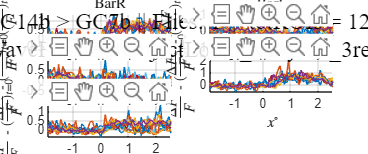

%% Plot 'Fig_05c': v = 240 & 480
Fig_02c = figure('Units', 'normalized', 'OuterPosition', [0, 0, 1, 1]);
for kk = 1:length(BarR)
    subplot(3,2,1); hold on; % Rbar subplot
    hold on;
    plot(t_s,BarR{kk,1})
    title('BarR', 'Interpreter', 'latex')
    % xline(-90, '-')
    % xline(90, '-')
    xlabel('$x^\circ$', 'Interpreter', 'latex');
    ylabel('$\frac{\Delta F}{F}$ - $(\frac{\Delta F}{F})_{t = 0}$', 'Interpreter', 'latex');
    grid on;
    % xlim([-95 115])
    subplot(3,2,2); hold on; % Lbar subplot
    plot(t_s,BarL{kk,1})
    title('BarL', 'Interpreter', 'latex')
    % xline(-90, '-')
    % xline(90, '-')
    xlabel('$x^\circ$', 'Interpreter', 'latex');
    ylabel('$\frac{\Delta F}{F}$ - $(\frac{\Delta F}{F})_{t = 0}$', 'Interpreter', 'latex');
    grid on;
    % xlim([-285 145])

    subplot(3,2,3); hold on; % Rbar subplot
    hold on;
    plot(t_s,ObjR{kk,1})
    title('ObjR', 'Interpreter', 'latex')
    % xline(-90, '-')
    % xline(90, '-')
    xlabel('$x^\circ$', 'Interpreter', 'latex');
    ylabel('$\frac{\Delta F}{F}$ - $(\frac{\Delta F}{F})_{t = 0}$', 'Interpreter', 'latex');
    grid on;
    % xlim([-95 115])
    subplot(3,2,4); hold on; % Lbar subplot
    plot(t_s,ObjL{kk,1})
    title('ObjL', 'Interpreter', 'latex')
    % xline(-90, '-')
    % xline(90, '-')
    xlabel('$x^\circ$', 'Interpreter', 'latex');
    ylabel('$\frac{\Delta F}{F}$ - $(\frac{\Delta F}{F})_{t = 0}$', 'Interpreter', 'latex');
    grid on;
    % xlim([-285 145])

    subplot(3,2,5); hold on; % Rbar subplot
    hold on;
    plot(t_s,LoomOFF{kk,1})
    title('LoomOFF', 'Interpreter', 'latex')
    % xline(-90, '-')
    % xline(90, '-')
    xlabel('$x^\circ$', 'Interpreter', 'latex');
    ylabel('$\frac{\Delta F}{F}$ - $(\frac{\Delta F}{F})_{t = 0}$', 'Interpreter', 'latex');
    grid on;
    % xlim([-95 115])
end
sgtitle({[num2str(param.cellType),' > ',num2str(param.sensor),' || Flies: ', num2str(info.analysis{1,1}.numFlies),' ||  totROIs = ', num2str(numROIs)], param.stim}, 'FontSize', 14, 'FontName', 'Times New Roman', 'Interpreter', 'none');

% end